# Lab 6.1

## 1.1

## 1.2

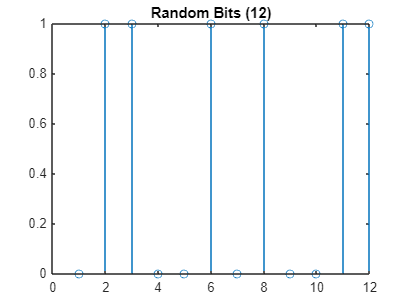

g = randbit(12);
stem(g);
title("Random Bits (12)");

## 1.3

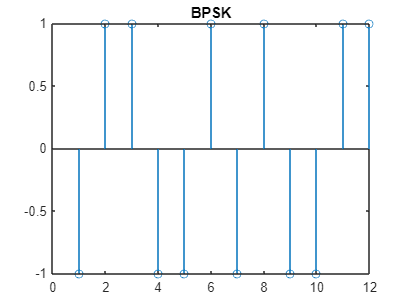

bpsk = bpskmap(g);
stem(bpsk);
title("BPSK");

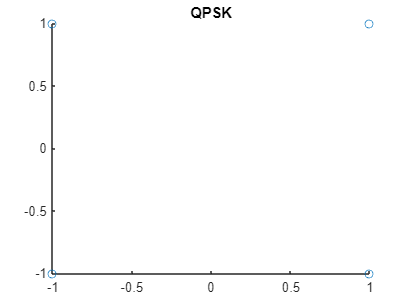


qpsk = qpskmap(g);
scatter(real(qpsk),imag(qpsk));
title("QPSK");

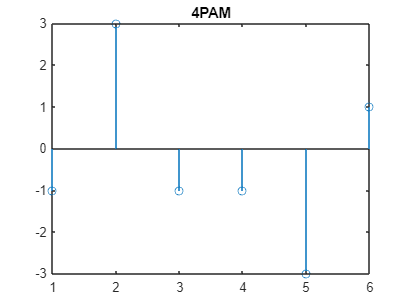


fourpam = fourpammap(g);
stem(fourpam);
title("4PAM");

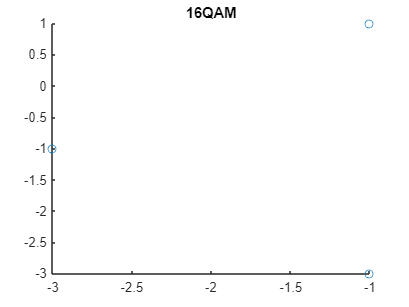


sixteenqam = sixteenqammap(g);
scatter(real(sixteenqam),imag(sixteenqam));
title("16QAM");

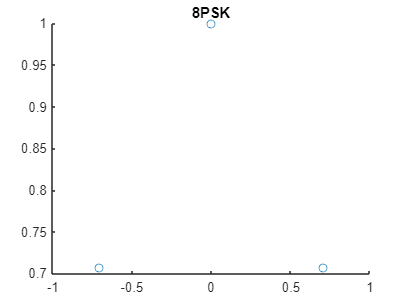


eightpsk = eightpskmap(g);
scatter(real(eightpsk),imag(eightpsk));
title("8PSK");

## 1.4

BPSKSignalPreMod = randbit(12000);
BPSKSignal = bpskmap(BPSKSignalPreMod);

length = 5;
a = 0.22;
m = 4;

[tx_output4] = s_tx_out(m,a,length,BPSKSignal); %%find Tx for a[n]

[rx_output4] = s_rx_out(m,a,length,tx_output4); %%find Rx for Tx for a[n]


for N=1:12000
    recieved_rx4(1,N) = rx_output4(100+(16*(N-1))); %%sample the Tx with a delay of 25 and m = 4
end




## 1.5

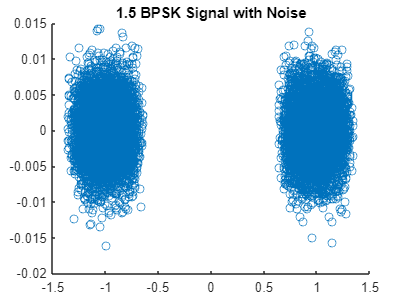

N0 = 2.997167926405326e-05;
sigma = sqrt(N0/2);
noise = (randn(48037,1)*sigma) + sqrt(-1)*(randn(48037,1)*sigma); %%Generate Gaussian Distribution;
var(noise);
std(noise);

[rx_noise5] = s_rx_out(m,a,length,noise); %%find Rx for noise

for N=1:12000
    recieved_noise5(1,N) = rx_noise5(100+(16*(N-1))); %%sample the Tx with a delay of 25 and m = 4
end

BPSKNoise = recieved_rx4 + recieved_noise5;

scatter(real(BPSKNoise),imag(BPSKNoise));
title("1.5 BPSK Signal with Noise");

## 1.6

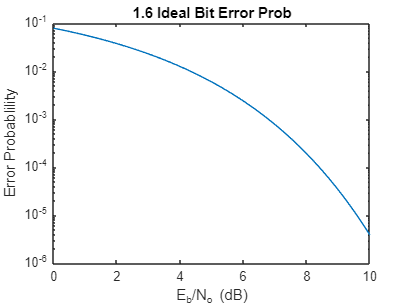

%%N0 = Eb/10^(db/10)
powerBPSK = bandpower(tx_output4);
powerBPSKpB = powerBPSK / 12000; %%Number of symbols

j=1;
for i=0:0.1:10
    
    t = 10^(i/10);
    IdBPSK(j,1) = qfunct(sqrt(2*(t)));
    j = j+1;
end

idx = 0:0.1:10;

rto = 10*log10(idx);

semilogy(idx,IdBPSK);
title("1.6 Ideal Bit Error Prob");
ylabel("Error Probablility");
xlabel("E_b/N_o (dB)");


%%E_b/N_0 = 4.3 
ratio = 10^(4.3/10);
N0 = powerBPSKpB / ratio; 





## 1.7

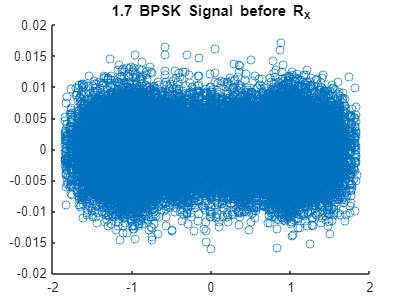


sigma = sqrt(N0/2);
noise7 = (randn(48037,1)*sigma) + sqrt(-1)*(randn(48037,1)*sigma); %%Generate Gaussian Distribution;

rx_input7 = noise7 + tx_output4;

[rx_output7] = s_rx_out(m,a,length,rx_input7); %%find Rx for noise

scatter(real(rx_input7),imag(rx_input7));
title("1.7 BPSK Signal before R_X");

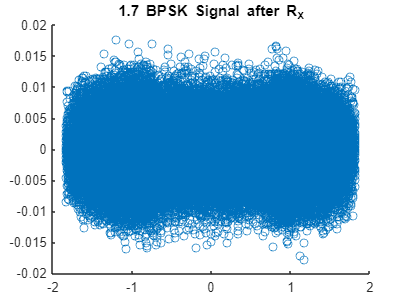


scatter(real(rx_output7),imag(rx_output7));
title("1.7 BPSK Signal after R_X");

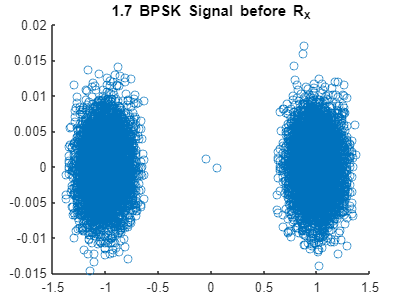


for N=1:12001
    insampled8(N,1) = rx_input7(25+(4*(N-1))); %%sample the Tx with a delay of 25 and m = 4
end

for N=1:12000
    recieved_noise7(N,1) = rx_output7(100+(16*(N-1))); %%sample the Tx with a delay of 25 and m = 4
end

scatter(real(insampled8),imag(insampled8));
title("1.7 BPSK Signal before R_X");

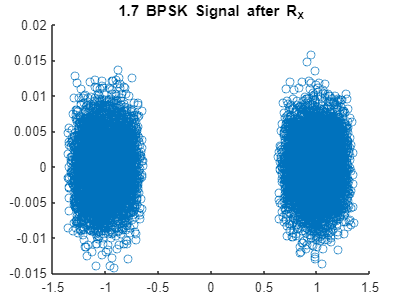


scatter(real(recieved_noise7),imag(recieved_noise7));
title("1.7 BPSK Signal after R_X");

## 1.8

inerror8 = 0;
outerror8 = 0;


for N = 1:12000
    
    if(real(insampled8(N,1)) > 0)
        rx_input7sam(N,1) = -1;
    else
        rx_input7sam(N,1) = 1;
        
    end
    if(real(recieved_noise7(N,1)) < 0)
        rx_output7sam(N,1) = -1;
    else 
        rx_output7sam(N,1) = 1;
    end

end

for N = 1:12000
    
    if((real(rx_input7sam(N,1))) ~= BPSKSignal(1,N))
        inerror8 = inerror8 + 1;
    end
    if((real(rx_output7sam(N,1))) ~= BPSKSignal(1,N))
        outerror8 = outerror8 + 1;
    end

end
Pinerr8 = inerror8/12000;
Pouterr8 = outerror8/12000;


## 1.9

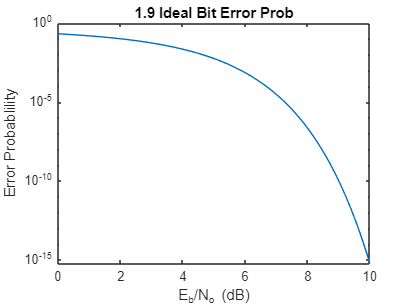

FOURPAMs = randbit(12000);
FOURPAM = fourpammap(FOURPAMs);

powerBPSK = bandpower(tx_output4);
powerBPSKpB = powerBPSK / 12000; %%Number of symbols

j=1;
for i=0:0.1:10
    
    t = 10^(i/10);
    IdBPSK(j,1) = qfunct((4/5)*t);
    j = j+1;
end

idx = 0:0.1:10;

rto = 10*log10(idx);

semilogy(idx,IdBPSK);
title("1.9 Ideal Bit Error Prob");
ylabel("Error Probablility");
xlabel("E_b/N_o (dB)");


%%E_b/N_0 = 4.3 
ratio = 10^(4.6/10);
N0 = powerBPSKpB / ratio; 
%%E_o/N_o = 4.6dB

## 1.10

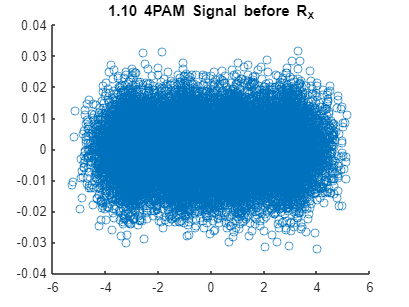


[tx_output10] = s_tx_out(m,a,length,FOURPAM); %%find Tx for a[n]

powerBPSK10 = bandpower(tx_output10);
powerBPSKpB10 = powerBPSK10 / 12000; %%Number of symbols

ratio = 10^(4.6/10);
N0 = powerBPSKpB10 / ratio; 

sigma = sqrt(N0/2);
noise10 = (randn(24037,1)*sigma) + sqrt(-1)*(randn(24037,1)*sigma); %%Generate Gaussian Distribution;


rx_input10 = noise10 + tx_output10;

[rx_output10] = s_rx_out(m,a,length,rx_input10); %%find Rx for noise


scatter(real(rx_input10),imag(rx_input10));
title("1.10 4PAM Signal before R_X");

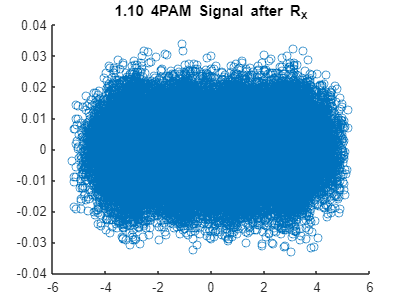


scatter(real(rx_output10),imag(rx_output10));
title("1.10 4PAM Signal after R_X");

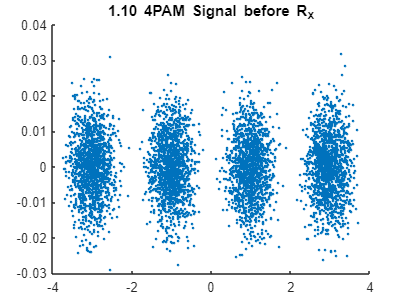


inerror10 = 0;
outerror10 = 0;

for N=1:6000
    insampled10(N,1) = rx_input10(25+(4*(N-1))); %%sample the Tx with a delay of 25 and m = 4
end

for N=1:6000
    recieved_noise10(N,1) = rx_output10(100+(16*(N-1))); %%sample the Tx with a delay of 25 and m = 4
end

scatter(real(insampled10),imag(insampled10),'.');
title("1.10 4PAM Signal before R_X");

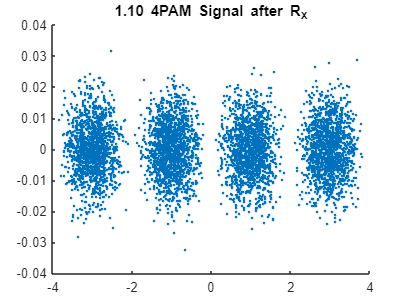


scatter(real(recieved_noise10),imag(recieved_noise10),'.');
title("1.10 4PAM Signal after R_X");


for N = 1:6000
    
    if(real(insampled10(N,1)) > 2)
        rx_input10sam(N,1) = 3;
    elseif(real(insampled10(N,1)) > 0)
        rx_input10sam(N,1) = 1;
    elseif(real(insampled10(N,1)) > -2)
        rx_input10sam(N,1) = -1;
    else
        rx_input10sam(N,1) = -3;
    end
    if(real(recieved_noise10(N,1)) > 2)
        rx_output10sam(N,1) = 3;
    elseif(real(recieved_noise10(N,1)) > 0) 
        rx_output10sam(N,1) = 1;
    elseif(real(recieved_noise10(N,1)) > -2)
        rx_output10sam(N,1) = -1;
    else
        rx_output10sam(N,1) = -3;
    end
end

for N = 1:6000
    
    if((real(rx_input10sam(N,1))) ~= FOURPAM(1,N))
        inerror10 = inerror10 + 1;
    end
    if((real(rx_output10sam(N,1))) ~= FOURPAM(1,N))
        outerror10 = outerror10 + 1;
    end

end

Pinerr10 = inerror10/6000;
Pouterr10 = outerror10/6000;


## 1.11

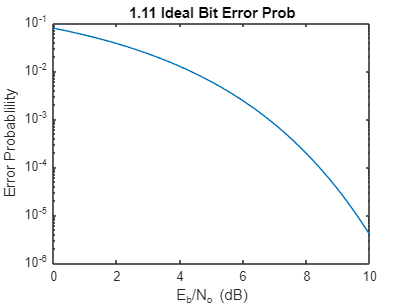

QPSKs = randbit(12000);
QPSK = qpskmap(QPSKs);

powerBPSK = bandpower(tx_output4)/2;
powerBPSKpB = powerBPSK / 6000; %%Number of symbols

j=1;
for i=0:0.1:10
    
    t = 10^(i/10);
    IdBPSK(j,1) = qfunct(sqrt(2*t));
    j = j+1;
end

idx = 0:0.1:10;

rto = 10*log10(idx);

semilogy(idx,IdBPSK);
title("1.11 Ideal Bit Error Prob");
ylabel("Error Probablility");
xlabel("E_b/N_o (dB)");

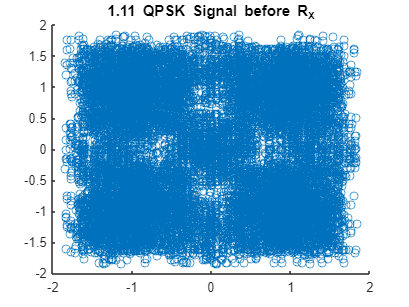


%%E_b/N_0 = 4.3 
ratio = 10^(4.3/10);
N0 = powerBPSKpB / ratio; 
%%E_o/N_o = 4.6dB



[tx_output11] = s_tx_out(m,a,length,QPSK); %%find Tx for a[n]

powerBPSK11 = bandpower(tx_output11)/2;
powerBPSKpB11 = powerBPSK11 / 6000; %%Number of symbols

ratio = 10^(4.3/10);
N0 = powerBPSKpB11 / ratio; 


sigma = sqrt(N0/2);
noise11 = (randn(24037,1)*sigma) + sqrt(-1)*(randn(24037,1)*sigma); %%Generate Gaussian Distribution;

rx_input11 = noise11 + tx_output11;

[rx_output11] = s_rx_out(m,a,length,rx_input11); %%find Rx for noise


scatter(real(rx_input11),imag(rx_input11));
title("1.11 QPSK Signal before R_X");

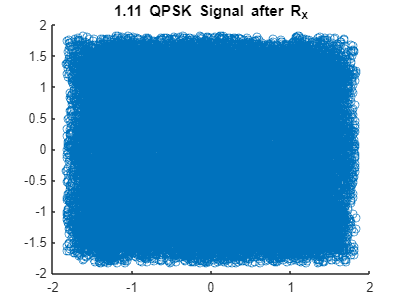


scatter(real(rx_output11),imag(rx_output11));
title("1.11 QPSK Signal after R_X");

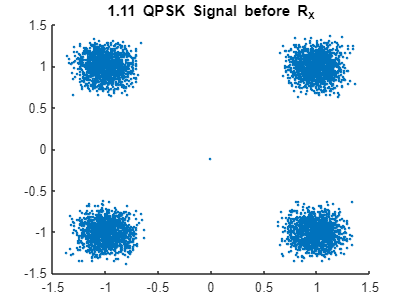


inerror11 = 0;
outerror11 = 0;

for N=1:6000
    insampled11(N,1) = rx_input11(25+(4*(N-1))); %%sample the Tx with a delay of 25 and m = 4
end

for N=1:6000
    recieved_noise11(N,1) = rx_output11(100+(16*(N-1))); %%sample the Tx with a delay of 25 and m = 4
end

scatter(real(insampled11),imag(insampled11),'.');
title("1.11 QPSK Signal before R_X");

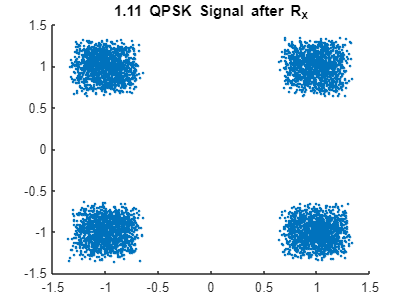


scatter(real(recieved_noise11),imag(recieved_noise11),'.');
title("1.11 QPSK Signal after R_X");


for N = 1:6000
    
    if(real(insampled11(N,1)) > 2)
        rx_input11sam(N,1) = 3;
    elseif(real(insampled11(N,1)) > 0)
        rx_input11sam(N,1) = 1;
    elseif(real(insampled11(N,1)) > -2)
        rx_input11sam(N,1) = -1;
    else
        rx_input11sam(N,1) = -3;
    end
    if(imag(insampled11(N,1)) > 2)
        rx_input11sam(N,1) = rx_input11sam(N,1) + 3*sqrt(-1);
    elseif(imag(insampled11(N,1)) > 0)
        rx_input11sam(N,1) = rx_input11sam(N,1) + sqrt(-1);
    elseif(imag(insampled11(N,1)) > -2)
       rx_input11sam(N,1) = rx_input11sam(N,1) - sqrt(-1);
    else
        rx_input11sam(N,1) = rx_input11sam(N,1) - 3*sqrt(-1);
    end
    if(real(recieved_noise11(N,1)) > 2)
        rx_output11sam(N,1) = 3;
    elseif(real(recieved_noise11(N,1)) > 0) 
        rx_output11sam(N,1) = 1;
    elseif(real(recieved_noise11(N,1)) > -2)
        rx_output11sam(N,1) = -1;
    else
        rx_output11sam(N,1) = -3;
    end
    if(imag(recieved_noise11(N,1)) > 2)
        rx_output11sam(N,1) = rx_output11sam(N,1) + 3*sqrt(-1);
    elseif(imag(recieved_noise11(N,1)) > 0) 
        rx_output11sam(N,1) = rx_output11sam(N,1) + sqrt(-1);
    elseif(imag(recieved_noise11(N,1)) > -2)
        rx_output11sam(N,1) = rx_output11sam(N,1) - sqrt(-1);
    else
        rx_output11sam(N,1) = rx_output11sam(N,1) -3*sqrt(-1);
    end
end

for N = 1:6000
    
    if((rx_input11sam(N,1)) ~= QPSK(1,N))
        inerror11 = inerror11 + 1;
    end
    if((rx_output11sam(N,1)) ~= QPSK(1,N))
        outerror11 = outerror11 + 1;
    end

end

Pinerr11 = inerror11/6000;
Pouterr11 = outerror11/6000;



## 1.12

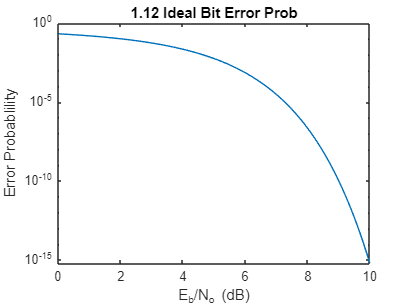


QAM16s = randbit(12000);
QAM16 = sixteenqammap(QAM16s);

powerBPSK = bandpower(tx_output4);
powerBPSKpB = powerBPSK / 12000; %%Number of symbols

j=1;
for i=0:0.1:10
    
    t = 10^(i/10);
    IdBPSK(j,1) = qfunct((4/5)*t);
    j = j+1;
end

idx = 0:0.1:10;

rto = 10*log10(idx);

semilogy(idx,IdBPSK);
title("1.12 Ideal Bit Error Prob");
ylabel("Error Probablility");
xlabel("E_b/N_o (dB)");

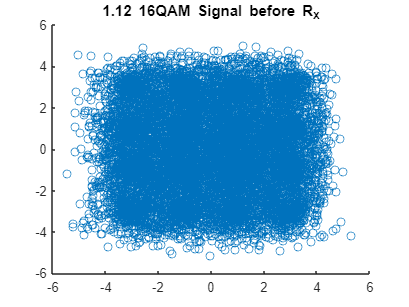


%%E_b/N_0 = 4.3 
ratio = 10^(4.6/10);
N0 = powerBPSKpB / ratio; 
%%E_o/N_o = 4.6dB

[tx_output12] = s_tx_out(m,a,length,QAM16); %%find Tx for a[n]

powerBPSK12 = bandpower(tx_output12)/4;
powerBPSKpB12 = powerBPSK12 / 3000; %%Number of symbols

ratio = 10^(4.6/10);
N0 = powerBPSKpB12 / ratio; 

sigma = sqrt(N0/2);
noise12 = (randn(12037,1)*sigma) + sqrt(-1)*(randn(12037,1)*sigma); %%Generate Gaussian Distribution;


rx_input12 = noise12 + tx_output12;

[rx_output12] = s_rx_out(m,a,length,rx_input12); %%find Rx for noise


scatter(real(rx_input12),imag(rx_input12));
title("1.12 16QAM Signal before R_X");

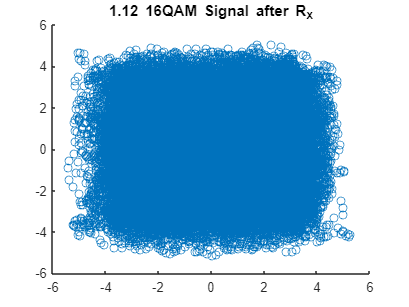


scatter(real(rx_output12),imag(rx_output12));
title("1.12 16QAM Signal after R_X");

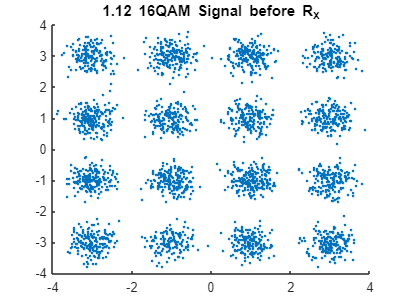


inerror12 = 0;
outerror12 = 0;

for N=1:3000
    insampled12(N,1) = rx_input12(25+(4*(N-1))); %%sample the Tx with a delay of 25 and m = 4
end

for N=1:3000
    recieved_noise12(N,1) = rx_output12(100+(16*(N-1))); %%sample the Tx with a delay of 25 and m = 4
end

scatter(real(insampled12),imag(insampled12),'.');
title("1.12 16QAM Signal before R_X");

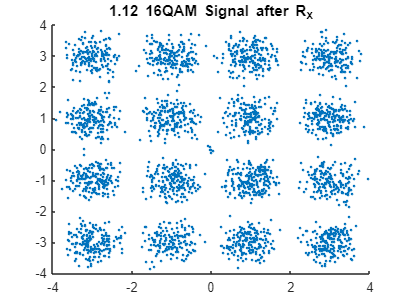


scatter(real(recieved_noise12),imag(recieved_noise12),'.');
title("1.12 16QAM Signal after R_X");


for N = 1:3000
    
    if(real(insampled12(N,1)) > 2)
        rx_input12sam(N,1) = 3;
    elseif(real(insampled12(N,1)) > 0)
        rx_input12sam(N,1) = 1;
    elseif(real(insampled12(N,1)) > -2)
        rx_input12sam(N,1) = -1;
    else
        rx_input12sam(N,1) = -3;
    end
    if(imag(insampled12(N,1)) > 2)
        rx_input12sam(N,1) = rx_input12sam(N,1) + 3*sqrt(-1);
    elseif(imag(insampled12(N,1)) > 0)
        rx_input12sam(N,1) = rx_input12sam(N,1) + 1*sqrt(-1);
    elseif(imag(insampled12(N,1)) > -2)
        rx_input12sam(N,1) = rx_input12sam(N,1) - 1*sqrt(-1);
    else
        rx_input12sam(N,1) = rx_input12sam(N,1) - 3*sqrt(-1);
    end
    if(real(recieved_noise12(N,1)) > 2)
        rx_output12sam(N,1) = 3;
    elseif(real(recieved_noise12(N,1)) > 0) 
        rx_output12sam(N,1) = 1;
    elseif(real(recieved_noise12(N,1)) > -2)
        rx_output12sam(N,1) = -1;
    else
        rx_output12sam(N,1) = -3;
    end
    if(imag(recieved_noise12(N,1)) > 2)
        rx_output12sam(N,1) = rx_output12sam(N,1) + 3*sqrt(-1);
    elseif(imag(recieved_noise12(N,1)) > 0)
        rx_output12sam(N,1) = rx_output12sam(N,1) + 1*sqrt(-1);
    elseif(imag(recieved_noise12(N,1)) > -2)
        rx_output12sam(N,1) = rx_output12sam(N,1) - 1*sqrt(-1);
    else
        rx_output12sam(N,1) = rx_output12sam(N,1) - 3*sqrt(-1);
    end
end

for N = 1:3000
    
    if((rx_input12sam(N,1)) ~= QAM16(1,N))
        inerror12 = inerror12 + 1;
    end
    if((rx_output12sam(N,1)) ~= QAM16(1,N))
        outerror12 = outerror12 + 1;
    end

end

Pinerr12 = inerror12/3000;
Pouterr12 = outerror12/3000;



## 1.13

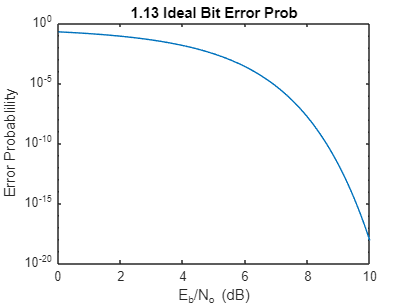


PSK8s = randbit(12000);
PSK8 = eightpskmap(PSK8s);

powerBPSK = bandpower(tx_output4);
powerBPSKpB = powerBPSK / 12000; %%Number of symbols

j=1;
for i=0:0.1:10
    
    t = 10^(i/10);
    IdBPSK(j,1) = qfunct(((6-3*sqrt(2))/2)*t);
    j = j+1;
end

idx = 0:0.1:10;

rto = 10*log10(idx);

semilogy(idx,IdBPSK);
title("1.13 Ideal Bit Error Prob");
ylabel("Error Probablility");
xlabel("E_b/N_o (dB)");

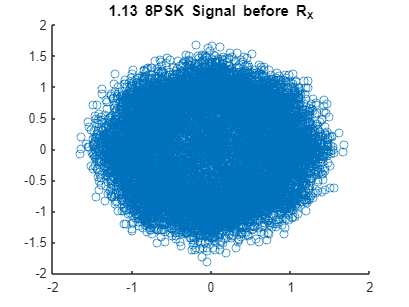


%%E_b/N_0 = 4.3 
ratio = 10^(4.2/10);
N0 = powerBPSKpB / ratio; 
%%E_o/N_o = 4.6dB

[tx_output13] = s_tx_out(m,a,length,PSK8); %%find Tx for a[n]

powerBPSK13 = bandpower(tx_output13)/3;
powerBPSKpB13 = powerBPSK13 / 4000; %%Number of symbols

ratio = 10^(4.2/10);
N0 = powerBPSKpB13 / ratio; 

sigma = sqrt(N0/2);
noise13 = (randn(16037,1)*sigma) + sqrt(-1)*(randn(16037,1)*sigma); %%Generate Gaussian Distribution;


rx_input13 = noise13 + tx_output13;

[rx_output13] = s_rx_out(m,a,length,rx_input13); %%find Rx for noise


scatter(real(rx_input13),imag(rx_input13));
title("1.13 8PSK Signal before R_X");

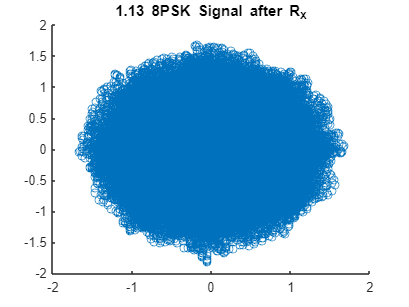


scatter(real(rx_output13),imag(rx_output13));
title("1.13 8PSK Signal after R_X");

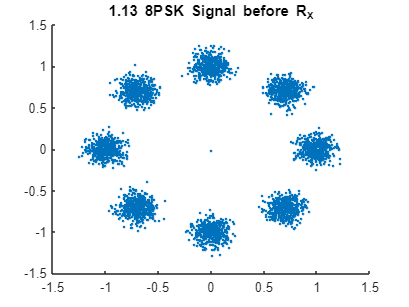


inerror13 = 0;
outerror13 = 0;

for N=1:4000
    insampled13(N,1) = rx_input13(25+(4*(N-1))); %%sample the Tx with a delay of 25 and m = 4
end

for N=1:4000
    recieved_noise13(N,1) = rx_output13(100+(16*(N-1))); %%sample the Tx with a delay of 25 and m = 4
end

scatter(real(insampled13),imag(insampled13),'.');
title("1.13 8PSK Signal before R_X");

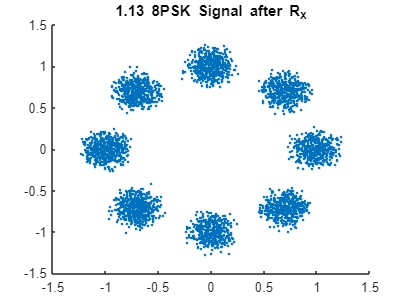


scatter(real(recieved_noise13),imag(recieved_noise13),'.');
title("1.13 8PSK Signal after R_X");


for N = 1:4000
    
    if(angle(rx_input13) > -7*pi/8 & angle(rx_input13)< (-5*pi)/8 )
        rx_input13sam(N,1) = exp(sqrt(-1)*2*pi*5/8);
    elseif(angle(rx_input13) >(-5*pi)/8 & angle(rx_input13)< (-3*pi)/8 )
        rx_input13sam(N,1) = exp(sqrt(-1)*2*pi*6/8);
    elseif(angle(rx_input13) >(-3*pi)/8 & angle(rx_input13)< (-1*pi)/8 )
        rx_input13sam(N,1) = exp(sqrt(-1)*2*pi*7/8);
    elseif(angle(rx_input13) >(-1*pi)/8 & angle(rx_input13)< (1*pi)/8 )
        rx_input13sam(N,1) = exp(sqrt(-1)*2*pi*0/8);
    elseif(angle(rx_input13) >(1*pi)/8 & angle(rx_input13)< (3*pi)/8 )
        rx_input13sam(N,1) = exp(sqrt(-1)*2*pi*1/8);
    elseif(angle(rx_input13) >(3*pi)/8 & angle(rx_input13)< (5*pi)/8 )
        rx_input13sam(N,1) = exp(sqrt(-1)*2*pi*2/8);
    elseif(angle(rx_input13) >(5*pi)/8 & angle(rx_input13)< (7*pi)/8 )
        rx_input13sam(N,1) = exp(sqrt(-1)*2*pi*3/8);
    else
        rx_input13sam(N,1) = exp(sqrt(-1)*2*pi*3/8);
    end

    if((angle(rx_output13) > -7*pi/8) & (angle(rx_output13)< (-5*pi)/8 ))
        rx_output13sam(N,1) = exp(sqrt(-1)*2*pi*5/8);
    elseif((angle(rx_output13) >(-5*pi)/8) & (angle(rx_output13)< (-3*pi)/8 ))
        rx_output13sam(N,1) = exp(sqrt(-1)*2*pi*6/8);
    elseif((angle(rx_output13) >(-3*pi)/8) & (angle(rx_output13)< (-1*pi)/8 ))
        rx_output13sam(N,1) = exp(sqrt(-1)*2*pi*7/8);
    elseif((angle(rx_output13) >(-1*pi)/8) & (angle(rx_output13)< (1*pi)/8 ))
        rx_output13sam(N,1) = exp(sqrt(-1)*2*pi*0/8);
    elseif((angle(rx_output13) >(1*pi)/8) & (angle(rx_output13)< (3*pi)/8 ))
        rx_output13sam(N,1) = exp(sqrt(-1)*2*pi*1/8);
    elseif((angle(rx_output13) >(3*pi)/8) & (angle(rx_output13)< (5*pi)/8 ))
        rx_output13sam(N,1) = exp(sqrt(-1)*2*pi*2/8);
    elseif((angle(rx_output13) >(5*pi)/8) & (angle(rx_output13)< (7*pi)/8 ))
        rx_output13sam(N,1) = exp(sqrt(-1)*2*pi*3/8);
    else
        rx_output13sam(N,1) = exp(sqrt(-1)*2*pi*3/8);
    end
   

end

for N = 1:4000
    
    if((rx_input13sam(N,1)) ~= PSK8(1,N))
        inerror13 = inerror12 + 1;
    end
    if((rx_output13sam(N,1)) ~= PSK8(1,N))
        outerror13 = outerror12 + 1;
    end

end

Pinerr13 = inerror13/4000;
Pouterr13 = outerror13/4000;






## 1.14


QAM16s = randbit(12000);
QAM16 = sixteenqammap(QAM16s);

powerBPSK = bandpower(tx_output4);
powerBPSKpB = powerBPSK / 12000; %%Number of symbols

j=1;
for i=0:0.1:10
    
    t = 10^(i/10);
    IdBPSK(j,1) = qfunct((4/5)*t);
    j = j+1;
end

idx = 0:0.1:10;

rto = 10*log10(idx);

semilogy(idx,IdBPSK);
title("1.12 Ideal Bit Error Prob");
ylabel("Error Probablility");
xlabel("E_b/N_o (dB)");

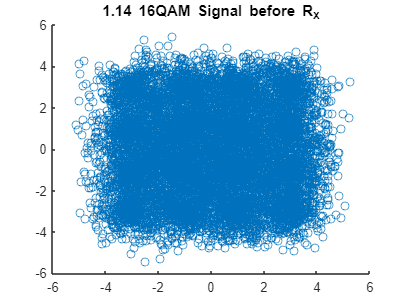


%%E_b/N_0 = 4.3 
ratio = 10^(7.6/10);
N0 = powerBPSKpB / ratio; 
%%E_o/N_o = 4.6dB

[tx_output12] = s_tx_out(m,a,length,QAM16); %%find Tx for a[n]

powerBPSK12 = bandpower(tx_output12)/4;
powerBPSKpB12 = powerBPSK12 / 3000; %%Number of symbols

ratio = 10^(4.6/10);
N0 = powerBPSKpB12 / ratio; 

sigma = sqrt(N0/2);
noise12 = (randn(12037,1)*sigma) + sqrt(-1)*(randn(12037,1)*sigma); %%Generate Gaussian Distribution;


rx_input12 = noise12 + tx_output12;

[rx_output12] = s_rx_out(m,a,length,rx_input12); %%find Rx for noise


scatter(real(rx_input12),imag(rx_input12));
title("1.14 16QAM Signal before R_X");

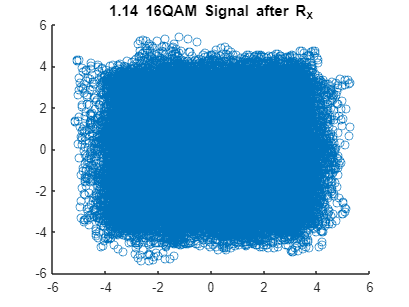


scatter(real(rx_output12),imag(rx_output12));
title("1.14 16QAM Signal after R_X");

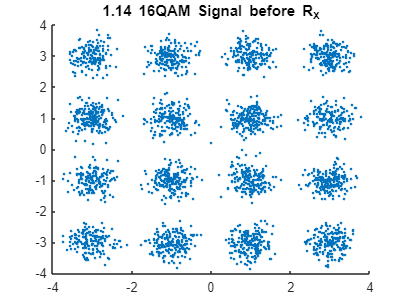


inerror12 = 0;
outerror12 = 0;

for N=1:3000
    insampled12(N,1) = rx_input12(25+(4*(N-1))); %%sample the Tx with a delay of 25 and m = 4
end

for N=1:3000
    recieved_noise12(N,1) = rx_output12(100+(16*(N-1))); %%sample the Tx with a delay of 25 and m = 4
end

scatter(real(insampled12),imag(insampled12),'.');
title("1.14 16QAM Signal before R_X");

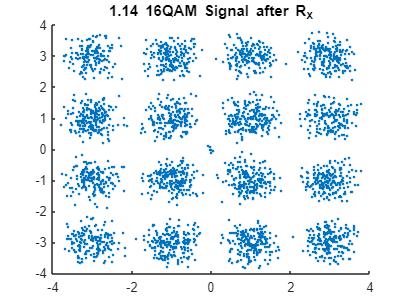


scatter(real(recieved_noise12),imag(recieved_noise12),'.');
title("1.14 16QAM Signal after R_X");


for N = 1:3000
    
    if(real(insampled12(N,1)) > 2)
        rx_input12sam(N,1) = 3;
    elseif(real(insampled12(N,1)) > 0)
        rx_input12sam(N,1) = 1;
    elseif(real(insampled12(N,1)) > -2)
        rx_input12sam(N,1) = -1;
    else
        rx_input12sam(N,1) = -3;
    end
    if(imag(insampled12(N,1)) > 2)
        rx_input12sam(N,1) = rx_input12sam(N,1) + 3*sqrt(-1);
    elseif(imag(insampled12(N,1)) > 0)
        rx_input12sam(N,1) = rx_input12sam(N,1) + 1*sqrt(-1);
    elseif(imag(insampled12(N,1)) > -2)
        rx_input12sam(N,1) = rx_input12sam(N,1) - 1*sqrt(-1);
    else
        rx_input12sam(N,1) = rx_input12sam(N,1) - 3*sqrt(-1);
    end
    if(real(recieved_noise12(N,1)) > 2)
        rx_output12sam(N,1) = 3;
    elseif(real(recieved_noise12(N,1)) > 0) 
        rx_output12sam(N,1) = 1;
    elseif(real(recieved_noise12(N,1)) > -2)
        rx_output12sam(N,1) = -1;
    else
        rx_output12sam(N,1) = -3;
    end
    if(imag(recieved_noise12(N,1)) > 2)
        rx_output12sam(N,1) = rx_output12sam(N,1) + 3*sqrt(-1);
    elseif(imag(recieved_noise12(N,1)) > 0)
        rx_output12sam(N,1) = rx_output12sam(N,1) + 1*sqrt(-1);
    elseif(imag(recieved_noise12(N,1)) > -2)
        rx_output12sam(N,1) = rx_output12sam(N,1) - 1*sqrt(-1);
    else
        rx_output12sam(N,1) = rx_output12sam(N,1) - 3*sqrt(-1);
    end
end

for N = 1:3000
    
    if((rx_input12sam(N,1)) ~= QAM16(1,N))
        inerror12 = inerror12 + 1;
    end
    if((rx_output12sam(N,1)) ~= QAM16(1,N))
        outerror12 = outerror12 + 1;
    end

end

Pinerr14 = inerror12/3000;
Pouterr14 = outerror12/3000;


